Robot1

L1(1) = Link('revolute','alpha',0,'a',0,'d',0.137,'offset',0,'modified');
L1(2) = Link('revolute','alpha',-pi/2,'a',0,'d',0,'offset',-pi/2,'qlim',[-pi/2 30*pi/180] ,'modified');
L1(3) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');
L1(4) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');

R_tool = [0  0  1;
         -1  0  0;
          0 -1  0];
P_tool = [0.11 0 0]';
T_4_tool = rt2tr(R_tool,P_tool);
R1 = SerialLink(L1,'name','phantom1');
R1.tool = T_4_tool;
R1

 
R1 = 
 
phantom1 (4 axis, RRRR, modDH, slowRNE)                                        
                                                                               
+---+-----------+-----------+-----------+-----------+-----------+              
| j |     theta |         d |         a |     alpha |    offset |              
+---+-----------+-----------+-----------+-----------+-----------+              
|  1|         q1|      0.137|          0|          0|          0|              
|  2|         q2|          0|          0|     -1.571|     -1.571|              
|  3|         q3|          0|      0.105|          0|          0|              
|  4|         q4|          0|      0.105|          0|          0|              
+---+-----------+-----------+-----------+-----------+-----------+              
                                                                               
grav =    0  base = 1  0  0  0   tool =   0           0           1        0.11
          0         0  1  0  0

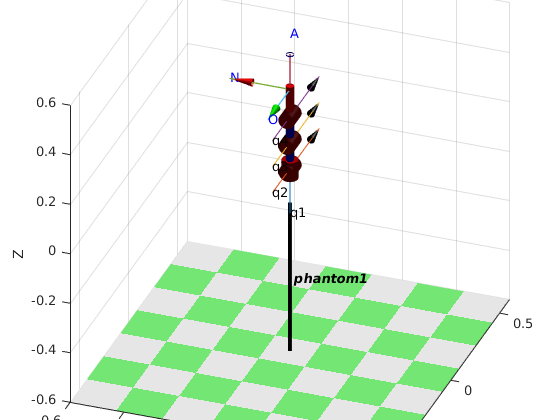




R1.plot([0 0 0 0],'noa','jvec','view',[20 30])

Robot2

L2(1) = Link('revolute','alpha',0,'a',0.5,'d',0.137,'offset',pi,'modified');
L2(2) = Link('revolute','alpha',-pi/2,'a',0,'d',0,'offset',-pi/2,'qlim',[-pi/2 30*pi/180] ,'modified');
L2(3) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');
L2(4) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');

R_tool = [0  0  1;
         -1  0  0;
          0 -1  0];
P_tool = [0.11 0 0]';
T_4_tool = rt2tr(R_tool,P_tool);
R2 = SerialLink(L2,'name','phantom2');
R2.tool = T_4_tool;
R2

 
R2 = 
 
phantom2 (4 axis, RRRR, modDH, slowRNE)                                        
                                                                               
+---+-----------+-----------+-----------+-----------+-----------+              
| j |     theta |         d |         a |     alpha |    offset |              
+---+-----------+-----------+-----------+-----------+-----------+              
|  1|         q1|      0.137|        0.5|          0|      3.142|              
|  2|         q2|          0|          0|     -1.571|     -1.571|              
|  3|         q3|          0|      0.105|          0|          0|              
|  4|         q4|          0|      0.105|          0|          0|              
+---+-----------+-----------+-----------+-----------+-----------+              
                                                                               
grav =    0  base = 1  0  0  0   tool =   0           0           1        0.11
          0         0  1  0  0

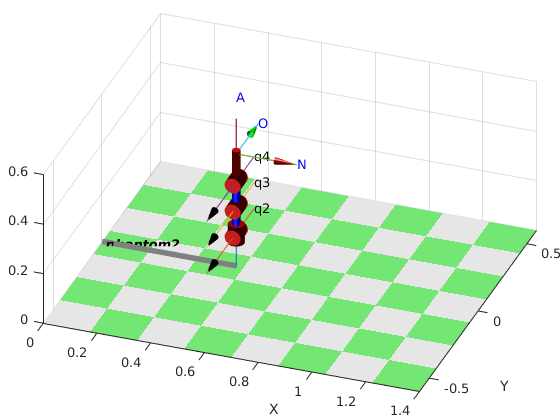




R2.plot([0 0 0 0],'workspace',[0 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

(correr esta y la siguiente sección por separado)

Mensajes

Vamos a provbar con el mismo punto para ver que ambos lleguen a dicho punto y de esta manera se comprueba que el S0 es el mismo para ambos robots.

Punto_aprox = [0 0 1 0.25;
               0 -1 0 0;
               1 0 0 0.2;
               0 0 0 1];
Punto_aprox2 = [0 0 1 0.25;
               0 -1 0 0;
               1 0 0 0.2;
               0 0 0 1];
qi_1 =  R1.ikunc(Punto_aprox);
qi_2 =  R2.ikunc(Punto_aprox2);
rosinit

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
Initializing global node /matlab_global_node_77500 with NodeURI http://julian-XPS-8700:38771/


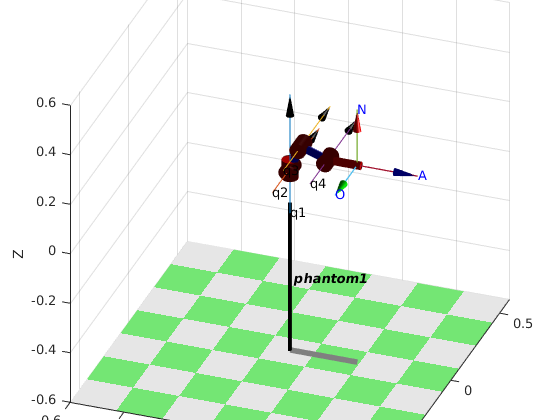

phantompos1 = rospublisher('/robot_1/phantom_position_controller/command');
message1 = rosmessage(phantompos1);
message1.Data = [qi_1 0 0];
R1.plot(qi_1,'noa','jvec','view',[20 30])
pause(1)

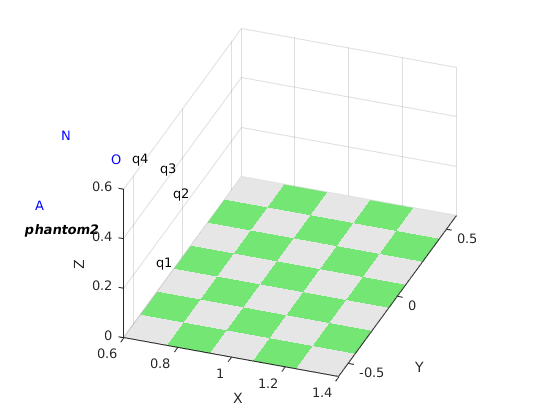

send(phantompos1,message1);
phantompos2 = rospublisher('/robot_2/phantom_position_controller/command');
message2 = rosmessage(phantompos2);
message2.Data = [qi_2 0 0];
R2.plot(qi_2,'workspace',[0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])
pause(1)

send(phantompos2,message2);
rosshutdown

Shutting down global node /matlab_global_node_77500 with NodeURI http://julian-XPS-8700:38771/


qi_1 = [1 -1 0.5 0];
qi_2 = [1 -1 0.5 0];
rosinit

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
Initializing global node /matlab_global_node_66148 with NodeURI http://julian-XPS-8700:43411/


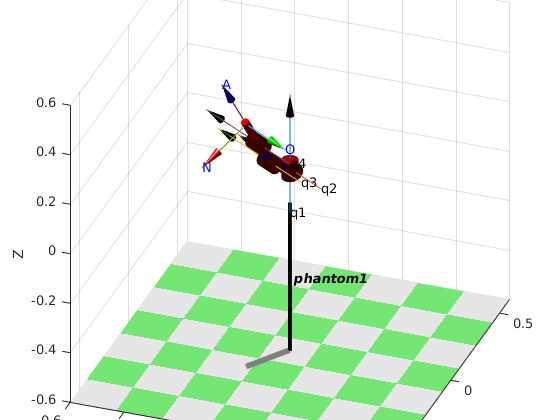

phantompos1 = rospublisher('/robot_1/phantom_position_controller/command');
message1 = rosmessage(phantompos1);
message1.Data = [qi_1 0 0];
R1.plot(qi_1,'noa','jvec','view',[20 30])
pause(1)

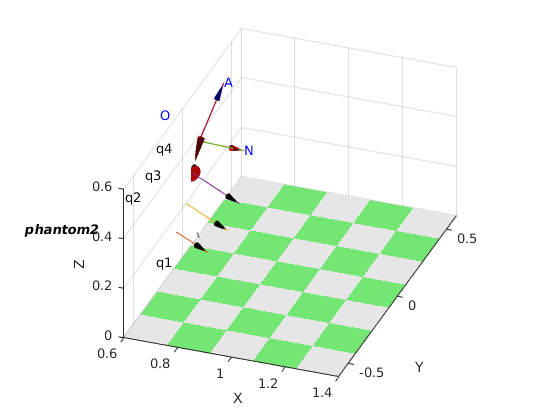

send(phantompos1,message1);
phantompos2 = rospublisher('/robot_2/phantom_position_controller/command');
message2 = rosmessage(phantompos2);
message2.Data = [qi_2 0 0];
R2.plot(qi_2,'workspace',[0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])
pause(1)

send(phantompos2,message2);
rosshutdown

Shutting down global node /matlab_global_node_66148 with NodeURI http://julian-XPS-8700:43411/
